% Matriz combinada con los datos obtenidos reales
tiempo_r = TimeSeconds(1:end-150);
distancia_r = 100*(SonarMeters(151:end) - ParedMeters(151:end))

distancia_r =   147.3932
  147.3932
  146.8818
  145.9074
  144.9292
  143.9507
  142.9726
  141.9965
  141.0183
  140.0400


flip(distancia_r)

ans =    16.4902
   16.4902
   16.4902
   16.4902
   16.4902
   16.4902
   16.4902
   16.4902
   16.4902
   16.4902


matriz_combinada_r_invertida = cat(2,tiempo_r, distancia_r);
matriz_combinada_v_invertida = cat(2,tiempo_v.', flip(distancia_v).');

% Depuración de la data
matriz_depurada_r_invertida = depura_matrices(matriz_combinada_r_invertida, 0, 6.7)

matriz_depurada_r_invertida =     0.0500  147.3932
    0.1000  146.8818
    0.1500  145.9074
    0.2000  144.9292
    0.2500  143.9507
    0.3000  142.9726
    0.3500  141.9965
    0.4000  141.0183
    0.4500  140.0400
    0.5000  139.0617


matriz_depurada_v_invertida = depura_matrices(matriz_combinada_v_invertida, 0, 6.7)

matriz_depurada_v_invertida = 134×2 single matrix
    0.0500  147.3000
    0.1000  146.4000
    0.1500  145.3000
    0.2000  144.4000
    0.2500  143.4000
    0.3000  142.4000
    0.3500  141.5000
    0.4000  140.5000
    0.4500  139.6000
    0.5000  138.6000


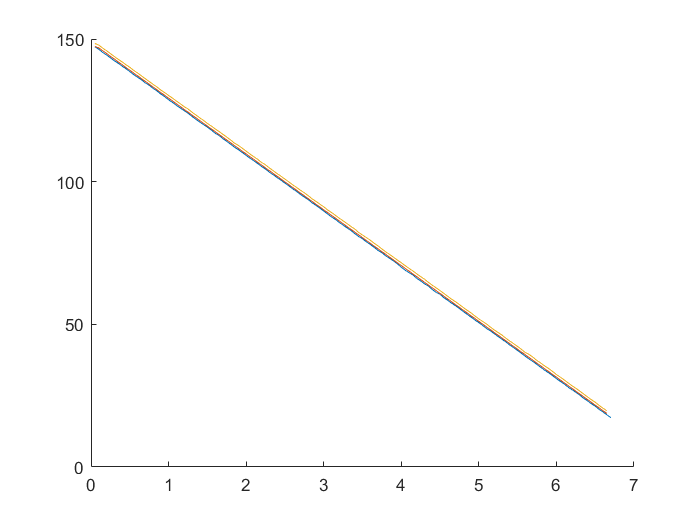


% Matriz invertida
hold on 
%plot(matriz_depurada_r_invertida(:,1).',matriz_depurada_r_invertida(:,2).')
plot(matriz_depurada_v_invertida(:,1).',matriz_depurada_v_invertida(:,2).')

% Muestra Regular
plot(matriz_depurada_r(:,1).',matriz_depurada_r(:,2).')
plot(matriz_depurada_v(:,1).',matriz_depurada_v(:,2).')
hold off

function matriz_limpia = depura_matrices(matriz, corte_inicio, corte_final)    
    matriz_limpia = [];
    for i = 1: size(matriz,1)
        if matriz(i,1) > corte_inicio && matriz(i,1) < corte_final
            matriz_limpia = [matriz_limpia; matriz(i,:)];
        end
    end
end
